# In-Class Quiz 2

A liquid is moving through a circular pipe (r = 3 cm) in fully developed laminar flow. The fluid viscosity is a function of temperature, u(T) = 0.6 * e^-0.008 * T. The pipe is slowly heated up (assume a homogeneous system with respect to temperature). Calculate the temperature (T, degrees C) to an error limit of 0.001 degrees C at which the fluid behavior starts to become turbulent. Show all calculations to obtain full credit. If partial credit is desired, clearly show method of solution.

The viscosity (u) is a funciton of temperature, u = 0.6 * e^-0.008*T, g/cm-s

The pressure drop (delta P), across the length of the pipe is constant, 70 g/cm-s^2.

The length of the pile (L) is 10 cm.

The density of the fluid (density) is constant at 2 g/cm^3.

Possibly useful information

At fully developed laminar flow, the radial velocity profile, v(r) is deltaP * R^2/ 4uL * (1 - r/R)^2

Turbulent flow starts when Reynolds number (Re) reaches 2300. Re = density * velocity * L / viscosity

Suggestions: Think about the behavior of the fluid as temperature increases. At what radial position in the pipe is the velocity greatest?

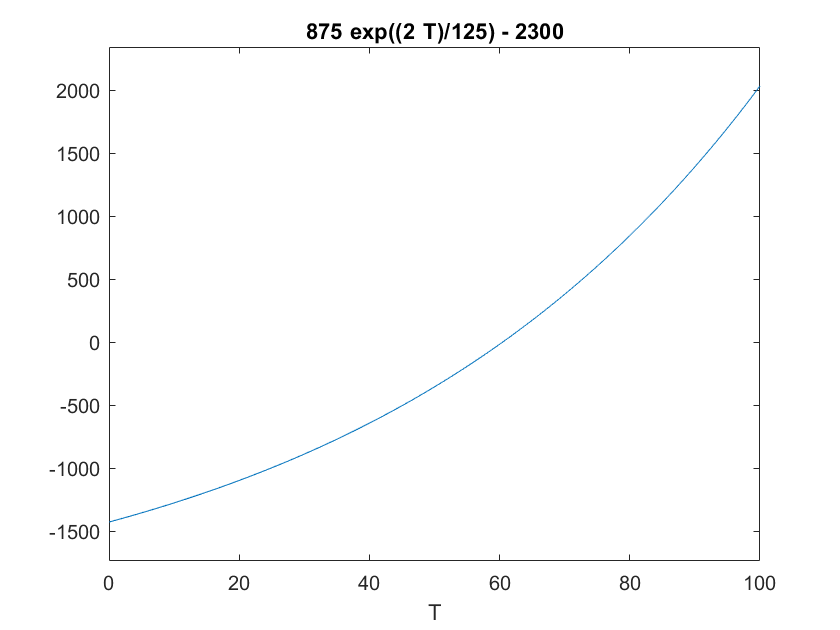

syms T
u = 0.6 * exp(-0.008 * T); % [g/cm-s]
R = 3; % [cm]
deltaP = 70; % [g/cm-s^2]
L = 10; % [cm]
density = 2; % [g/cm^3]
velocity = deltaP * R^2 / (4 * u * L); % [cm/s]
Re = density * velocity * L / u - 2300; % [-]
ezplot(Re,[0,100])

[x_root, i] = newton_raphson(Re,0,0.001)

x_root = 60.4025

i = 5

function [x_root, i] = newton_raphson(f, x1, error_tol)
    T      = x1;
    zero   = double(subs(f));                                  % sets zero to the value of the 
                                                                   % function at the given x 
                                                                   % point
    x_root = x1;                                               % renames input x value
    i      = 0;                                                % sets iteration counter to zero 
    while abs(zero) > error_tol                                % checks to see if another 
                                                                   % iteration should be 
                                                                   % performed
        T     = x_root;
        slope = double(subs(diff(f)));                         % finds the slope of the function 
                                                                   % at the given point
        if slope == 0                                          % checks for a minimum or maximum
            fprintf('Error: stuck at minimum or maximum of function.')
            zero   = 0;                                        % breaks the while loop so that the 
                                                                   % function doesn't go on forever
            x_root = 'N/A'; 
        else
            b      = zero - slope * x_root;                    % finds the b of the function 
                                                                   % y = mx + b
            x_root = double(-b / slope);                       % finds the new x where y = 0 for 
                                                                   % the linear function
            T      = x_root;
            zero   = double(subs(f));                          % finds the value of the function 
                                                                   % at the x found above
            i      = i + 1;                                    % adds iteration to counter
        end
    end
    if x_root == 'N/A'                                         % changes the zero value to N/A in 
                                                                   % the case that a maximum was 
                                                                   % found after loop break
        zero  = 'N/A';
    end
end